clc
clear

x = [0,1,2,3,4,5,6,7,8,9,10,11,12,13,14,15];
f=poisspdf(x,4)

f =     0.0183    0.0733    0.1465    0.1954    0.1954    0.1563    0.1042    0.0595    0.0298    0.0132    0.0053    0.0019    0.0006    0.0002    0.0001    0.0000


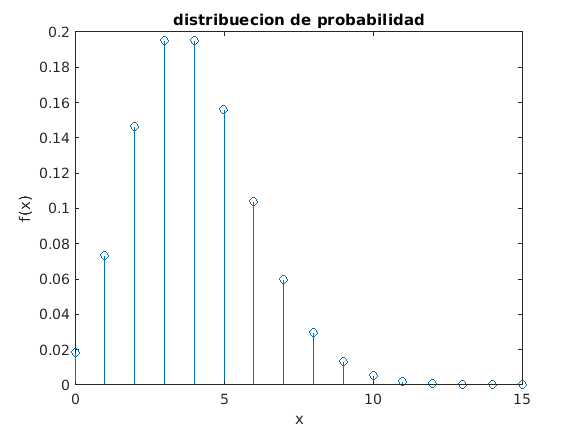

F=cumsum(f);
%grafica de distribucion de probabilidad
stem(x,f);
title('distribuecion de probabilidad')
xlabel('x')
ylabel('f(x)')

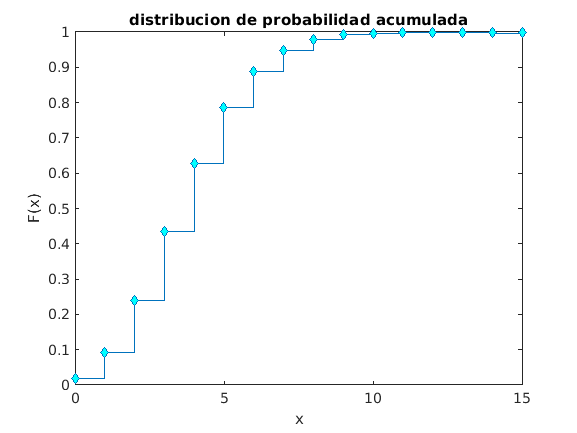

%grafica de distribucion de probabilidad acumulada
stairs(x,F,'LineWidth',1,'Marker','d','MarkerFaceColor','c')
title('distribucion de probabilidad acumulada')
xlabel('x')
ylabel('F(x)')

%encontrar los errores en 100 dias

%encontrar la media z(x)
Ez=0;
for i=1:1:16
    Ez=Ez+(((20*x(i)+3)^2)*f(i));
end
Ez

Ez = 8.4885e+03

%encontrar la varianza z(x)
Vz=0;
for i=1:1:16
    Vz=Vz+((((20*x(i)+3)^2)-Ez)^2)*f(i);
end
Vz

Vz = 6.0424e+07

xa=[300,400,500];
fa=poisspdf(xa,400)

fa =     0.0000    0.0199    0.0000
